close all
clear variables
load census;

#### 1. Импорт данных

data1 = readmatrix("data1.txt");
data2 = readmatrix("data2.txt");

OX1 = data1(:, 1);
OY1 = data1(:, 2);

[f, gof] = fit(OX1, OY1, 'poly2');

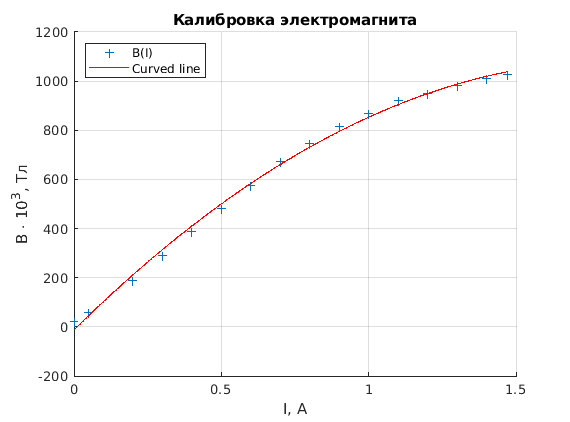

graph1 = figure;

hold on;
    plot(f, OX1, OY1, '+');
hold off;

set   (graph1, 'Visible', 'on'); 
xlabel('I, A');
ylabel('B \cdot 10^3, Тл'); 
title ('Калибровка электромагнита');
legend('B(I)', 'Curved line', 'Location','northwest');

grid on; 
saveas(graph1, './images/graph1.png');

OX = data2(:, 1);
Y1 = data2(:, 2);
Y2 = data2(:, 3);
Y3 = data2(:, 4);
Y4 = data2(:, 5);
Y5 = data2(:, 6);
Y6 = data2(:, 7);

[f1, gof1] = fit(OX, Y1, 'poly1')

f1 =      Linear model Poly1:
     f1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   5.895e-05  (5.739e-05, 6.05e-05)
       p2 =  -0.0006193  (-0.001684, 0.0004451)

gof1 = struct with fields:
           sse: 2.2624e-06
       rsquare: 0.9993
           dfe: 6
    adjrsquare: 0.9992
          rmse: 6.1405e-04


[f2, gof2] = fit(OX, Y2, 'poly1')

f2 =      Linear model Poly1:
     f2(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0001372  (0.0001346, 0.0001399)
       p2 =     -0.0021  (-0.003913, -0.0002884)

gof2 = struct with fields:
           sse: 6.5569e-06
       rsquare: 0.9996
           dfe: 6
    adjrsquare: 0.9996
          rmse: 0.0010


[f3, gof3] = fit(OX, Y3, 'poly1')

f3 =      Linear model Poly1:
     f3(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0002058  (0.0002028, 0.0002087)
       p2 =   -0.003409  (-0.005429, -0.00139)

gof3 = struct with fields:
           sse: 8.1441e-06
       rsquare: 0.9998
           dfe: 6
    adjrsquare: 0.9998
          rmse: 0.0012


[f4, gof4] = fit(OX, Y4, 'poly1')

f4 =      Linear model Poly1:
     f4(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0002765  (0.0002713, 0.0002817)
       p2 =   -0.004882  (-0.008434, -0.00133)

gof4 = struct with fields:
           sse: 2.5199e-05
       rsquare: 0.9996
           dfe: 6
    adjrsquare: 0.9996
          rmse: 0.0020


[f5, gof5] = fit(OX, Y5, 'poly1')

f5 =      Linear model Poly1:
     f5(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0003477  (0.0003337, 0.0003616)
       p2 =   -0.008899  (-0.01846, 0.0006607)

gof5 = struct with fields:
           sse: 1.8250e-04
       rsquare: 0.9984
           dfe: 6
    adjrsquare: 0.9981
          rmse: 0.0055


[f6, gof6] = fit(OX, Y6, 'poly1')

f6 =      Linear model Poly1:
     f6(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0004165  (0.00041, 0.000423)
       p2 =   -0.007377  (-0.01184, -0.002914)

gof6 = struct with fields:
           sse: 3.9789e-05
       rsquare: 0.9998
           dfe: 6
    adjrsquare: 0.9997
          rmse: 0.0026


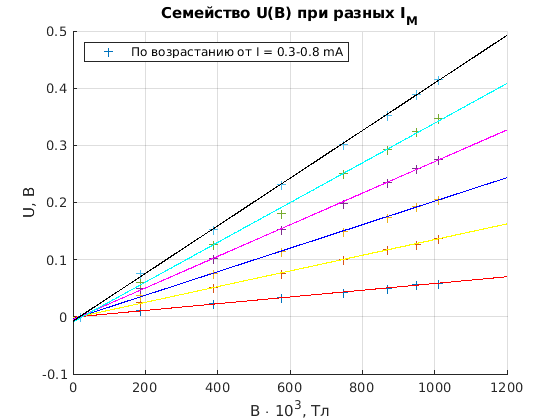

graph2 = figure;

hold on;    
    plot(OX, Y1, '+');
    plot(OX, Y2, '+');
    plot(OX, Y3, '+');
    plot(OX, Y4, '+');
    plot(OX, Y5, '+');
    plot(OX, Y6, '+');
    
    plot(f1, 'r');
    plot(f2, 'y');
    plot(f3, 'b');
    plot(f4, 'm');
    plot(f5, 'c');
    plot(f6, 'k');
hold off;

set   (graph2, 'Visible', 'on'); 
xlabel('B \cdot 10^3, Тл');
ylabel('U, В'); 
title ('Семейство U(B) при разных I_M');
legend('По возрастанию от I = 0.3-0.8 mA', 'Location','northwest');

grid on; 
saveas(graph2, './images/graph2.png');

I = [0.3 , 0.4 , 0.5 , 0.6 , 0.7 , 0.8 ]';
k = [0.59, 1.37, 2.05, 2.77, 3.47, 4.17]';

[fk, gofk] = fit(I, k, 'poly1')

fk =      Linear model Poly1:
     fk(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        7.12  (6.95, 7.29)
       p2 =      -1.513  (-1.61, -1.415)

gofk = struct with fields:
           sse: 0.0026
       rsquare: 0.9997
           dfe: 4
    adjrsquare: 0.9996
          rmse: 0.0256


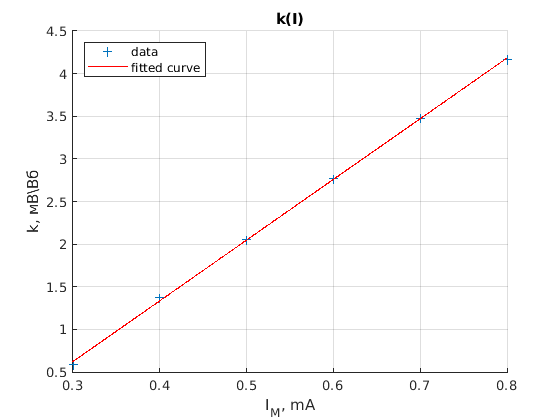


graph3 = figure;

hold on;    
    plot(fk, I, k, '+');
hold off;

set   (graph3, 'Visible', 'on'); 
xlabel('I_M, mA');
ylabel('k, мВ\Вб'); 
title ('k(I)');
legend('Location','northwest');

grid on; 
saveas(graph3, './images/graph3.png');

#### 6. Построение графика спектров всех звёзд

%graphStars = figure;

%hold on;
%for indxGraph = 1 : numStars
%    if speed(indxGraph) > 0
%        plot(lambda, spectra(:, indxGraph), ...
%             '-', ...
%             'Linewidth', 3);
%    else 
%        plot(lambda, spectra(:, indxGraph), ...
%             '--', ...
%             'Linewidth', 1); 
%    end
%end
%hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

%set   (graphStars, 'Visible', 'on'); 
%xlabel('Длина волны, нм');
%ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
%title ('Спектры звёзд');
%legend(starNames);
%grid on;
%saveas(graphStars, 'spectra.png');